# 'plot' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Create *povlab* object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Create scene

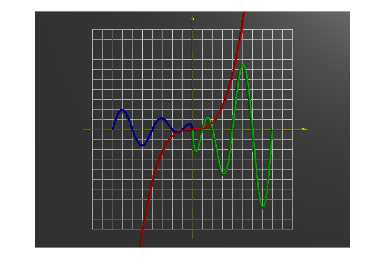

% TODO: Set image size
pl.scene_begin('scene_file', 'plot.pov', 'image_file', 'plot.png');
pl.include("shapes");

pl.global_settings("assumed_gamma 1");

% Camera
pl.camera('angle', 35, 'location', [0 0 50], 'look_at', [0 0 0], 'type', 'orthographic');

% Light
pl.light('location', [20 20 20], 'color', [0.9 0.9 0.9]);

% Axis
%pl.axis('length', [11 11 0], 'radius', 0.08 );
tex_axis_yellow = pl.declare("tex_axis_yellow", pl.texture('pigment', [1.0 1.0 0.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
tex_axis_gray   = pl.declare("tex_axis_gray", pl.texture('pigment', [0.5 0.5 0.5], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
pl.axis('length', [11 11 0], 'radius', 0.08, 'tex_common', tex_axis_gray, 'tex_x', tex_axis_yellow, 'tex_y', tex_axis_yellow);

% Axis plane
tex_plane = pl.declare("tex_plane_blue",  pl.texture('pigment', [0.3 0.3 0.3], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
pl.plane('normal', [0,0,1], 'distance', 0, 'texture', tex_plane,  'scale', [1 1 1], 'rotate', [0 0 0], 'translate', [0 0 0]);

% Grid
pl.grid('width', 20, 'height', 20, 'radius', 0.03 , 'rotate', [90 0  0], 'translate', [0 0 0]);
% tex_grid_blue = pl.declare("tex_grid_blue", pl.texture('pigment', [0.4 0.9 1.0], 'finish', "phong 1 reflection {0.10 metallic 0.4}"));
% pl.grid('width', 20, 'height', 20, 'radius', 0.04, 'texture_odd', tex_grid_blue, 'texture_even', tex_grid_blue, 'rotate', [90 0  0], 'translate', [0 0 0]);

% Plot
pl.plot('name', 'fgreen', 'funcion', '4 * sin(X * pi/2) * ln(X)', ...
         'min_x', 0, 'max_x', 8, 'color', [0 0.8 0.0], ...
         'width', 0.1, 'translate', [0 0 0.1]);

pl.plot('name', 'fyellow', 'funcion', 'sin(X * pi/2) * ln(-X)', ...
         'min_x', -8, 'max_x', 0, 'color', [0 0.0 0.8], ...
         'width', 0.1, 'translate', [0 0 0.1]);

pl.plot('name', 'fred', 'funcion', 'X * X * X / 12', ...
         'min_x', -8, 'max_x', 8, 'color', [1 0.0 0.0], ...
         'width', 0.1, 'translate', [0 0 0.1]);

pl.scene_end();
image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 2.633778 seconds.
